addpath(genpath('VNA'));


## Connect to SubArray

array = subArray_controller('COM57');

Connected to COM57 at 115200 baud


array.targetModuleID = 0;
array.targetBoardID = 0;

array.mcu_reInitFromEEPROM()

Response: Done. -- #0


array.mcu_setDevMode(true)

Response: Done. -- #0


array.mcu_readBoardID()

Response: 0
Done. -- #0


ans =     '0
     Done. -- #0
     '


% array.fpga_init();



array.fpga_switchTXRX(0, 'rx');

Response: Done. -- #1


array.fpga_writeIFDSA(0, 32, true);

Response: Done. -- #1


array.allOff();

Response: Done. -- #1


## TR选项


isTX = 0;

if isTX == 1
    mode_TR = 'tx';
elseif isTX == 0
    mode_TR = 'rx';
else
    error('isTX must be 1 or 0');
end

PS_Chip_ID_list = double(~isTX) * 4 + (0:3);


## 设置衰减，清空AC和BF

array.fpga_writeAtten(8, 0, 64);

Response: ¢one. -- #0


array.fpga_writeAtten(8, 1, 64);

Response: Done. -- #0



array.fpga_writePhase(8, 0, 'AC', 0);

Response: Done. -- #0


array.fpga_writePhase(8, 1, 'AC', 0);

Response: Done. -- #0


array.fpga_writePhase(8, 0, 'BF', 0);

Response: Done. -- #0


array.fpga_writePhase(8, 1, 'BF', 0);

Response: Done. -- #0


array.fpga_writeIFDSA(2, 32, true);

Response: Done. -- #0


## 初始化矢网


VNA_USE = '3672E';

VNA_Init;

Connected to: "vna"




Freq_MK2_point = 1:201;
N_freq_p = length(Freq_MK2_point);

% S12, S21 在 rawData 中的列索引，请在 VNA_Single_Sweep 中检查。
S12_index = 3;
S21_index = 2;
% 转台上的设备接矢网端口1，因此当 isTX = True 时，S21表示增益。否则 S12表示增益。
if isTX
    Sp_index = S21_index;
else
    Sp_index = S12_index;
end

VNA_Single_Sweep;

#0,	System Error(s): +0,"No error"


## 遍历通道，测量不同幅度控制字下的增益

pause(15); % 15s离开暗室，关门
now = datetime('now','Format','y-MM-dd HH:mm:ss')

now = datetime
   2026-03-13 10:43:09



loop = 1;
atten_ASB = uint8(0:8:255);
N_atten_test = length(atten_ASB);

amp = zeros(N_freq_p, N_atten_test, 8); % MATLAB最低的维度（列）在最前面

for Channel_i = 0:7
    VNA_Single_Sweep_Fast_loopIndicator.j=Channel_i;    
    % 打开该通道
    array.fpga_switchTXRX(Channel_i, mode_TR);

    for atten_j = 1:N_atten_test
        
        % 向该通道写入幅度控制字
        array.fpga_writeAtten(PS_Chip_ID_list(bitshift(Channel_i, -1) + 1), mod(Channel_i,2), atten_ASB(atten_j));
        
        VNA_Single_Sweep_Fast_loopIndicator.k=atten_j;
    
        % 多次采集取平均
        a = zeros(loop, N_freq_p);
        for j = 1:loop
            VNA_Single_Sweep_Fast;
            a(j, :) = 20*log10((sparamMag(Freq_MK2_point, Sp_index)).');
        end
    
        amp(:, atten_j, Channel_i + 1) = mean(a, 1);

    end

    % 关闭通道
    array.fpga_switchTXRX(Channel_i, 'off');

end

Response: Done. -- #0


Response: Done. -- #0


#0,0,1...


Response: Done. -- #0


#0,0,2...


Response: Done. -- #0


#0,0,3...


Response: Done. -- #0


#0,0,4...


Response: Done. -- #0


#0,0,5...


Response: Done. -- #0


#0,0,6...


Response: Done. -- #0


#0,0,7...


Response: Done. -- #0


#0,0,8...


Response: Done. -- #0


#0,0,9...


Response: Done. -- #0


#0,0,10...


Response: Done. -- #0


#0,0,11...


Response: Done. -- #0


#0,0,12...


Response: Done. -- #0


#0,0,13...


Response: Done. -- #0


#0,0,14...


Response: Done. -- #0


#0,0,15...


Response: Done. -- #0


#0,0,16...


Response: Done. -- #0


#0,0,17...


Response: Done. -- #0


#0,0,18...


Response: Done. -- #0


#0,0,19...


Response: Done. -- #0


#0,0,20...


Response: Done. -- #0


#0,0,21...


Response: Done. -- #0


#0,0,22...


Response: Done. -- #0


#0,0,23...


Response: Done. -- #0


#0,0,24...


Response: Done. -- #0


#0,0,25...


Response: Done. -- #0


#0,0,26...


Response: Done. -- #0


#0,0,27...


Response: Done. -- #0


#0,0,28...


Response: Done. -- #0


#0,0,29...


Response: Done. -- #0


#0,0,30...


Response: Done. -- #0


#0,0,31...


Response: Done. -- #0


#0,0,32...


Response: Done. -- #0


Response: Done. -- #0


Response: Done. -- #0


#0,1,1...


Response: Done. -- #0


#0,1,2...


Response: Done. -- #0


#0,1,3...


Response: Done. -- #0


#0,1,4...


Response: Done. -- #0


#0,1,5...


Response: Done. -- #0


#0,1,6...


Response: Done. -- #0


#0,1,7...


Response: Done. -- #0


#0,1,8...


Response: Done. -- #0


#0,1,9...


Response: Done. -- #0


#0,1,10...


Response: Done. -- #0


#0,1,11...


Response: Done. -- #0


#0,1,12...


Response: Done. -- #0


#0,1,13...


Response: Done. -- #0


#0,1,14...


Response: Done. -- #0


#0,1,15...


Response: Done. -- #0


#0,1,16...


Response: Done. -- #0


#0,1,17...


Response: Done. -- #0


#0,1,18...


Response: Done. -- #0


#0,1,19...


Response: Done. -- #0


#0,1,20...


Response: Done. -- #0


#0,1,21...


Response: Done. -- #0


#0,1,22...


Response: Done. -- #0


#0,1,23...


Response: Done. -- #0


#0,1,24...


Response: Done. -- #0


#0,1,25...


Response: Done. -- #0


#0,1,26...


Response: Done. -- #0


#0,1,27...


Response: Done. -- #0


#0,1,28...


Response: Done. -- #0


#0,1,29...


Response: Done. -- #0


#0,1,30...


Response: Done. -- #0


#0,1,31...


Response: Done. -- #0


#0,1,32...


Response: Done. -- #0


Response: Done. -- #0


Response: Done. -- #0


#0,2,1...


Response: Done. -- #0


#0,2,2...


Response: Done. -- #0


#0,2,3...


Response: Done. -- #0


#0,2,4...


Response: Done. -- #0


#0,2,5...


Response: Done. -- #0


#0,2,6...


Response: Done. -- #0


#0,2,7...


Response: Done. -- #0


#0,2,8...


Response: Done. -- #0


#0,2,9...


Response: Done. -- #0


#0,2,10...


Response: Done. -- #0


#0,2,11...


Response: Done. -- #0


#0,2,12...


Response: Done. -- #0


#0,2,13...


Response: Done. -- #0


#0,2,14...


Response: Done. -- #0


#0,2,15...


Response: Done. -- #0


#0,2,16...


Response: Done. -- #0


#0,2,17...


Response: Done. -- #0


#0,2,18...


Response: Done. -- #0


#0,2,19...


Response: Done. -- #0


#0,2,20...


Response: Done. -- #0


#0,2,21...


Response: Done. -- #0


#0,2,22...


Response: Done. -- #0


#0,2,23...


Response: Done. -- #0


#0,2,24...


Response: Done. -- #0


#0,2,25...


Response: Done. -- #0


#0,2,26...


Response: Done. -- #0


#0,2,27...


Response: Done. -- #0


#0,2,28...


Response: Done. -- #0


#0,2,29...


Response: Done. -- #0


#0,2,30...


Response: Done. -- #0


#0,2,31...


Response: Done. -- #0


#0,2,32...


Response: Done. -- #0


Response: Done. -- #0


Response: Done. -- #0


#0,3,1...


Response: Done. -- #0


#0,3,2...


Response: Done. -- #0


#0,3,3...


Response: Done. -- #0


#0,3,4...


Response: Done. -- #0


#0,3,5...


Response: Done. -- #0


#0,3,6...


Response: Done. -- #0


#0,3,7...


Response: Done. -- #0


#0,3,8...


Response: Done. -- #0


#0,3,9...


Response: Done. -- #0


#0,3,10...


Response: Done. -- #0


#0,3,11...


Response: Done. -- #0


#0,3,12...


Response: Done. -- #0


#0,3,13...


Response: Done. -- #0


#0,3,14...


Response: Done. -- #0


#0,3,15...


Response: Done. -- #0


#0,3,16...


Response: Done. -- #0


#0,3,17...


Response: Done. -- #0


#0,3,18...


Response: Done. -- #0


#0,3,19...


Response: Done. -- #0


#0,3,20...


Response: Done. -- #0


#0,3,21...


Response: Done. -- #0


#0,3,22...


Response: Done. -- #0


#0,3,23...


Response: Done. -- #0


#0,3,24...


Response: Done. -- #0


#0,3,25...


Response: Done. -- #0


#0,3,26...


Response: Done. -- #0


#0,3,27...


Response: Done. -- #0


#0,3,28...


Response: Done. -- #0


#0,3,29...


Response: Done. -- #0


#0,3,30...


Response: Done. -- #0


#0,3,31...


Response: Done. -- #0


#0,3,32...


Response: Done. -- #0


Response: Done. -- #0


Response: Done. -- #0


#0,4,1...


Response: Done. -- #0


#0,4,2...


Response: Done. -- #0


#0,4,3...


Response: Done. -- #0


#0,4,4...


Response: Done. -- #0


#0,4,5...


Response: Done. -- #0


#0,4,6...


Response: Done. -- #0


#0,4,7...


Response: Done. -- #0


#0,4,8...


Response: Done. -- #0


#0,4,9...


Response: Done. -- #0


#0,4,10...


Response: Done. -- #0


#0,4,11...


Response: Done. -- #0


#0,4,12...


Response: Done. -- #0


#0,4,13...


Response: Done. -- #0


#0,4,14...


Response: Done. -- #0


#0,4,15...


Response: Done. -- #0


#0,4,16...


Response: Done. -- #0


#0,4,17...


Response: Done. -- #0


#0,4,18...


Response: Done. -- #0


#0,4,19...


Response: Done. -- #0


#0,4,20...


Response: Done. -- #0


#0,4,21...


Response: Done. -- #0


#0,4,22...


Response: Done. -- #0


#0,4,23...


Response: Done. -- #0


#0,4,24...


Response: Done. -- #0


#0,4,25...


Response: Done. -- #0


#0,4,26...


Response: Done. -- #0


#0,4,27...


Response: Done. -- #0


#0,4,28...


Response: Done. -- #0


#0,4,29...


Response: Done. -- #0


#0,4,30...


Response: Done. -- #0


#0,4,31...


Response: Done. -- #0


#0,4,32...


Response: Done. -- #0


Response: Done. -- #0


Response: Done. -- #0


#0,5,1...


Response: Done. -- #0


#0,5,2...


Response: Done. -- #0


#0,5,3...


Response: Done. -- #0


#0,5,4...


Response: Done. -- #0


#0,5,5...


Response: Done. -- #0


#0,5,6...


Response: Done. -- #0


#0,5,7...


Response: Done. -- #0


#0,5,8...


Response: Done. -- #0


#0,5,9...


Response: Done. -- #0


#0,5,10...


Response: Done. -- #0


#0,5,11...


Response: Done. -- #0


#0,5,12...


Response: Done. -- #0


#0,5,13...


Response: Done. -- #0


#0,5,14...


Response: Done. -- #0


#0,5,15...


Response: Done. -- #0


#0,5,16...


Response: Done. -- #0


#0,5,17...


Response: Done. -- #0


#0,5,18...


Response: Done. -- #0


#0,5,19...


Response: Done. -- #0


#0,5,20...


Response: Done. -- #0


#0,5,21...


Response: Done. -- #0


#0,5,22...


Response: Done. -- #0


#0,5,23...


Response: Done. -- #0


#0,5,24...


Response: Done. -- #0


#0,5,25...


Response: Done. -- #0


#0,5,26...


Response: Done. -- #0


#0,5,27...


Response: Done. -- #0


#0,5,28...


Response: Done. -- #0


#0,5,29...


Response: Done. -- #0


#0,5,30...


Response: Done. -- #0


#0,5,31...


Response: Done. -- #0


#0,5,32...


Response: Done. -- #0


Response: Done. -- #0


Response: Done. -- #0


#0,6,1...


Response: Done. -- #0


#0,6,2...


Response: Done. -- #0


#0,6,3...


Response: Done. -- #0


#0,6,4...


Response: Done. -- #0


#0,6,5...


Response: Done. -- #0


#0,6,6...


Response: Done. -- #0


#0,6,7...


Response: Done. -- #0


#0,6,8...


Response: Done. -- #0


#0,6,9...


Response: Done. -- #0


#0,6,10...


Response: Done. -- #0


#0,6,11...


Response: Done. -- #0


#0,6,12...


Response: Done. -- #0


#0,6,13...


Response: Done. -- #0


#0,6,14...


Response: Done. -- #0


#0,6,15...


Response: Done. -- #0


#0,6,16...


Response: Done. -- #0


#0,6,17...


Response: Done. -- #0


#0,6,18...


Response: Done. -- #0


#0,6,19...


Response: Done. -- #0


#0,6,20...


Response: Done. -- #0


#0,6,21...


Response: Done. -- #0


#0,6,22...


Response: Done. -- #0


#0,6,23...


Response: Done. -- #0


#0,6,24...


Response: Done. -- #0


#0,6,25...


Response: Done. -- #0


#0,6,26...


Response: Done. -- #0


#0,6,27...


Response: Done. -- #0


#0,6,28...


Response: Done. -- #0


#0,6,29...


Response: Done. -- #0


#0,6,30...


Response: Done. -- #0


#0,6,31...


Response: Done. -- #0


#0,6,32...


Response: Done. -- #0


Response: Done. -- #0


Response: Done. -- #0


#0,7,1...


Response: Done. -- #0


#0,7,2...


Response: Done. -- #0


#0,7,3...


Response: Done. -- #0


#0,7,4...


Response: Done. -- #0


#0,7,5...


Response: Done. -- #0


#0,7,6...


Response: Done. -- #0


#0,7,7...


Response: Done. -- #0


#0,7,8...


Response: Done. -- #0


#0,7,9...


Response: Done. -- #0


#0,7,10...


Response: Done. -- #0


#0,7,11...


Response: Done. -- #0


#0,7,12...


Response: Done. -- #0


#0,7,13...


Response: Done. -- #0


#0,7,14...


Response: Done. -- #0


#0,7,15...


Response: Done. -- #0


#0,7,16...


Response: Done. -- #0


#0,7,17...


Response: Done. -- #0


#0,7,18...


Response: Done. -- #0


#0,7,19...


Response: Done. -- #0


#0,7,20...


Response: Done. -- #0


#0,7,21...


Response: Done. -- #0


#0,7,22...


Response: Done. -- #0


#0,7,23...


Response: Done. -- #0


#0,7,24...


Response: Done. -- #0


#0,7,25...


Response: Done. -- #0


#0,7,26...


Response: Done. -- #0


#0,7,27...


Response: Done. -- #0


#0,7,28...


Response: Done. -- #0


#0,7,29...


Response: Done. -- #0


#0,7,30...


Response: Done. -- #0


#0,7,31...


Response: Done. -- #0


#0,7,32...


Response: Done. -- #0


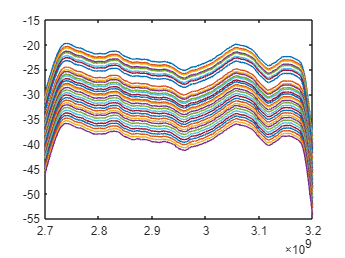



figure;
faxis = freqRange(Freq_MK2_point);

plot(faxis, amp(:,1,1));

hold on;

for atten_j = 2:N_atten_test
    plot(faxis, amp(:, atten_j, 1));
end

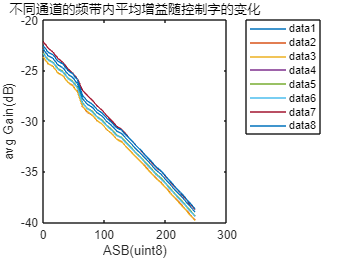



amp_freqavg = mean(amp, 1);

figure;
plot(atten_ASB, amp_freqavg(1,:,1))
hold on;

for Channel_i = 1:7
    plot(atten_ASB, amp_freqavg(1,:,Channel_i+1))
end
title('不同通道的频带内平均增益随控制字的变化');
xlabel('ASB(uint8)');
ylabel('avg Gain(dB)');

lg = legend('Location', 'bestoutside');

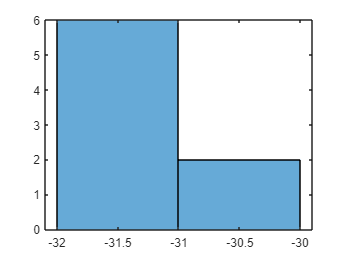

lg.ItemHitFcn=@HitCallbackFcn;


amp_attenfreqavg = mean(amp_freqavg, 2);

figure;
histogram(amp_attenfreqavg)


maxInconsistency = max(amp_attenfreqavg) - min(amp_attenfreqavg);

if maxInconsistency > 5
    error('有通道差异显著');
end



## 保存文件


nameDirection = char('RX' + 'T'*(isTX) - 'R'*(isTX) - [0 2*isTX])

nameDirection = 'TX'


nameTime = char(datetime('now','Format','yMMddHHmm'));

nameDirectory = 'mat\SubArrayTest';

mkdir(nameDirectory)



fileName=[nameDirectory '\M' num2str(array.targetModuleID) 'B' num2str(array.targetBoardID) '_' nameDirection '_amp_' nameTime '.mat'];
save(fileName, 'amp');



## 调整幅度控制字到合适水平，开始测量相位

array.fpga_writeAtten(8, 0, 64);
array.fpga_writeAtten(8, 1, 64);

Response: Done. -- #5
Done. -- #5



array.fpga_writePhase(8, 0, 'AC', 0);

Response: Done. -- #5


array.fpga_writePhase(8, 1, 'AC', 0);

Response: Done. -- #5


array.fpga_writePhase(8, 0, 'BF', 0);

Response: Done. -- #5


array.fpga_writePhase(8, 1, 'BF', 0);

Response: Done. -- #5


array.fpga_writeIFDSA(2, 32, true);

Response: Done. -- #5


## 遍历通道，测量不同相位控制字下的S参数相位


now = datetime('now','Format','y-MM-dd HH:mm:ss')

now = datetime
   2026-01-07 03:41:28



loop = 1;

phase_PSB = uint8(0:4:255);
N_phase_test = length(phase_PSB);

pha = zeros(N_freq_p, N_phase_test, 8); % MATLAB最低的维度（列）在最前面

for Channel_i = 0:7
    VNA_Single_Sweep_Fast_loopIndicator.j=Channel_i;    
    % 打开该通道
    array.fpga_switchTXRX(Channel_i, mode_TR);

    for phase_j = 1:N_phase_test
        
        % 向该通道写入相位控制字
        array.fpga_writePhase(PS_Chip_ID_list(bitshift(Channel_i, -1) + 1), mod(Channel_i,2), 'AC', phase_PSB(phase_j));
        array.fpga_updatePhase();
        VNA_Single_Sweep_Fast_loopIndicator.k=phase_j;
    
        % 多次采集取平均
        p = zeros(loop, N_freq_p);
        for j = 1:loop
            VNA_Single_Sweep_Fast;
            p(j, :) = (sparamPhase(Freq_MK2_point, Sp_index).')/pi*180;
        end
    
        pha(:, phase_j, Channel_i + 1) = mean(p, 1);

    end

    % 关闭通道
    array.fpga_switchTXRX(Channel_i, 'off');

end

Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


#0,0,1...


Response: Done. -- #5


Response: Done. -- #5


#0,0,2...


Response: Done. -- #5


Response: Done. -- #5


#0,0,3...


Response: Done. -- #5


Response: Done. -- #5


#0,0,4...


Response: Done. -- #5


Response: Done. -- #5


#0,0,5...


Response: Done. -- #5


Response: Done. -- #5


#0,0,6...


Response: Done. -- #5


Response: Done. -- #5


#0,0,7...


Response: Done. -- #5


Response: Done. -- #5


#0,0,8...


Response: Done. -- #5


Response: Done. -- #5


#0,0,9...


Response: Done. -- #5


Response: Done. -- #5


#0,0,10...


Response: Done. -- #5


Response: Done. -- #5


#0,0,11...


Response: Done. -- #5


Response: Done. -- #5


#0,0,12...


Response: Done. -- #5


Response: Done. -- #5


#0,0,13...


Response: Done. -- #5


Response: Done. -- #5


#0,0,14...


Response: Done. -- #5


Response: Done. -- #5


#0,0,15...


Response: Done. -- #5


Response: Done. -- #5


#0,0,16...


Response: Done. -- #5


Response: Done. -- #5


#0,0,17...


Response: Done. -- #5


Response: Done. -- #5


#0,0,18...


Response: Done. -- #5


Response: Done. -- #5


#0,0,19...


Response: Done. -- #5


Response: Done. -- #5


#0,0,20...


Response: Done. -- #5


Response: Done. -- #5


#0,0,21...


Response: Done. -- #5


Response: Done. -- #5


#0,0,22...


Response: Done. -- #5


Response: Done. -- #5


#0,0,23...


Response: Done. -- #5


Response: Done. -- #5


#0,0,24...


Response: Done. -- #5


Response: Done. -- #5


#0,0,25...


Response: Done. -- #5


Response: Done. -- #5


#0,0,26...


Response: Done. -- #5


Response: Done. -- #5


#0,0,27...


Response: Done. -- #5


Response: Done. -- #5


#0,0,28...


Response: Done. -- #5


Response: Done. -- #5


#0,0,29...


Response: Done. -- #5


Response: Done. -- #5


#0,0,30...


Response: Done. -- #5


Response: Done. -- #5


#0,0,31...


Response: Done. -- #5


Response: Done. -- #5


#0,0,32...


Response: Done. -- #5


Response: Done. -- #5


#0,0,33...


Response: Done. -- #5


Response: Done. -- #5


#0,0,34...


Response: Done. -- #5


Response: Done. -- #5


#0,0,35...


Response: Done. -- #5


Response: Done. -- #5


#0,0,36...


Response: Done. -- #5


Response: Done. -- #5


#0,0,37...


Response: Done. -- #5


Response: Done. -- #5


#0,0,38...


Response: Done. -- #5


Response: Done. -- #5


#0,0,39...


Response: Done. -- #5


Response: Done. -- #5


#0,0,40...


Response: Done. -- #5


Response: Done. -- #5


#0,0,41...


Response: Done. -- #5


Response: Done. -- #5


#0,0,42...


Response: Done. -- #5


Response: Done. -- #5


#0,0,43...


Response: Done. -- #5


Response: Done. -- #5


#0,0,44...


Response: Done. -- #5


Response: Done. -- #5


#0,0,45...


Response: Done. -- #5


Response: Done. -- #5


#0,0,46...


Response: Done. -- #5


Response: Done. -- #5


#0,0,47...


Response: Done. -- #5


Response: Done. -- #5


#0,0,48...


Response: Done. -- #5


Response: Done. -- #5


#0,0,49...


Response: Done. -- #5


Response: Done. -- #5


#0,0,50...


Response: Done. -- #5


Response: Done. -- #5


#0,0,51...


Response: Done. -- #5


Response: Done. -- #5


#0,0,52...


Response: Done. -- #5


Response: Done. -- #5


#0,0,53...


Response: Done. -- #5


Response: Done. -- #5


#0,0,54...


Response: Done. -- #5


Response: Done. -- #5


#0,0,55...


Response: Done. -- #5


Response: Done. -- #5


#0,0,56...


Response: Done. -- #5


Response: Done. -- #5


#0,0,57...


Response: Done. -- #5


Response: Done. -- #5


#0,0,58...


Response: Done. -- #5


Response: Done. -- #5


#0,0,59...


Response: Done. -- #5


Response: Done. -- #5


#0,0,60...


Response: Done. -- #5


Response: Done. -- #5


#0,0,61...


Response: Done. -- #5


Response: Done. -- #5


#0,0,62...


Response: Done. -- #5


Response: Done. -- #5


#0,0,63...


Response: Done. -- #5


Response: Done. -- #5


#0,0,64...


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


#0,1,1...


Response: Done. -- #5


Response: Done. -- #5


#0,1,2...


Response: Done. -- #5


Response: Done. -- #5


#0,1,3...


Response: Done. -- #5


Response: Done. -- #5


#0,1,4...


Response: Done. -- #5


Response: Done. -- #5


#0,1,5...


Response: Done. -- #5


Response: Done. -- #5


#0,1,6...


Response: Done. -- #5


Response: Done. -- #5


#0,1,7...


Response: Done. -- #5


Response: Done. -- #5


#0,1,8...


Response: Done. -- #5


Response: Done. -- #5


#0,1,9...


Response: Done. -- #5


Response: Done. -- #5


#0,1,10...


Response: Done. -- #5


Response: Done. -- #5


#0,1,11...


Response: Done. -- #5


Response: Done. -- #5


#0,1,12...


Response: Done. -- #5


Response: Done. -- #5


#0,1,13...


Response: Done. -- #5


Response: Done. -- #5


#0,1,14...


Response: Done. -- #5


Response: Done. -- #5


#0,1,15...


Response: Done. -- #5


Response: Done. -- #5


#0,1,16...


Response: Done. -- #5


Response: Done. -- #5


#0,1,17...


Response: Done. -- #5


Response: Done. -- #5


#0,1,18...


Response: Done. -- #5


Response: Done. -- #5


#0,1,19...


Response: Done. -- #5


Response: Done. -- #5


#0,1,20...


Response: Done. -- #5


Response: Done. -- #5


#0,1,21...


Response: Done. -- #5


Response: Done. -- #5


#0,1,22...


Response: Done. -- #5


Response: Done. -- #5


#0,1,23...


Response: Done. -- #5


Response: Done. -- #5


#0,1,24...


Response: Done. -- #5


Response: Done. -- #5


#0,1,25...


Response: Done. -- #5


Response: Done. -- #5


#0,1,26...


Response: Done. -- #5


Response: Done. -- #5


#0,1,27...


Response: Done. -- #5


Response: Done. -- #5


#0,1,28...


Response: Done. -- #5


Response: Done. -- #5


#0,1,29...


Response: Done. -- #5


Response: Done. -- #5


#0,1,30...


Response: Done. -- #5


Response: Done. -- #5


#0,1,31...


Response: Done. -- #5


Response: Done. -- #5


#0,1,32...


Response: Done. -- #5


Response: Done. -- #5


#0,1,33...


Response: Done. -- #5


Response: Done. -- #5


#0,1,34...


Response: Done. -- #5


Response: Done. -- #5


#0,1,35...


Response: Done. -- #5


Response: Done. -- #5


#0,1,36...


Response: Done. -- #5


Response: Done. -- #5


#0,1,37...


Response: Done. -- #5


Response: Done. -- #5


#0,1,38...


Response: Done. -- #5


Response: Done. -- #5


#0,1,39...


Response: Done. -- #5


Response: Done. -- #5


#0,1,40...


Response: Done. -- #5


Response: Done. -- #5


#0,1,41...


Response: Done. -- #5


Response: Done. -- #5


#0,1,42...


Response: Done. -- #5


Response: Done. -- #5


#0,1,43...


Response: Done. -- #5


Response: Done. -- #5


#0,1,44...


Response: Done. -- #5


Response: Done. -- #5


#0,1,45...


Response: Done. -- #5


Response: Done. -- #5


#0,1,46...


Response: Done. -- #5


Response: Done. -- #5


#0,1,47...


Response: Done. -- #5


Response: Done. -- #5


#0,1,48...


Response: Done. -- #5


Response: Done. -- #5


#0,1,49...


Response: Done. -- #5


Response: Done. -- #5


#0,1,50...


Response: Done. -- #5


Response: Done. -- #5


#0,1,51...


Response: Done. -- #5


Response: Done. -- #5


#0,1,52...


Response: Done. -- #5


Response: Done. -- #5


#0,1,53...


Response: Done. -- #5


Response: Done. -- #5


#0,1,54...


Response: Done. -- #5


Response: Done. -- #5


#0,1,55...


Response: Done. -- #5


Response: Done. -- #5


#0,1,56...


Response: Done. -- #5


Response: Done. -- #5


#0,1,57...


Response: Done. -- #5


Response: Done. -- #5


#0,1,58...


Response: Done. -- #5


Response: Done. -- #5


#0,1,59...


Response: Done. -- #5


Response: Done. -- #5


#0,1,60...


Response: Done. -- #5


Response: Done. -- #5


#0,1,61...


Response: Done. -- #5


Response: Done. -- #5


#0,1,62...


Response: Done. -- #5


Response: Done. -- #5


#0,1,63...


Response: Done. -- #5


Response: Done. -- #5


#0,1,64...


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


#0,2,1...


Response: Done. -- #5


Response: Done. -- #5


#0,2,2...


Response: Done. -- #5


Response: Done. -- #5


#0,2,3...


Response: Done. -- #5


Response: Done. -- #5


#0,2,4...


Response: Done. -- #5


Response: Done. -- #5


#0,2,5...


Response: Done. -- #5


Response: Done. -- #5


#0,2,6...


Response: Done. -- #5


Response: Done. -- #5


#0,2,7...


Response: Done. -- #5


Response: Done. -- #5


#0,2,8...


Response: Done. -- #5


Response: Done. -- #5


#0,2,9...


Response: Done. -- #5


Response: Done. -- #5


#0,2,10...


Response: Done. -- #5


Response: Done. -- #5


#0,2,11...


Response: Done. -- #5


Response: Done. -- #5


#0,2,12...


Response: Done. -- #5


Response: Done. -- #5


#0,2,13...


Response: Done. -- #5


Response: Done. -- #5


#0,2,14...


Response: Done. -- #5


Response: Done. -- #5


#0,2,15...


Response: Done. -- #5


Response: Done. -- #5


#0,2,16...


Response: Done. -- #5


Response: Done. -- #5


#0,2,17...


Response: Done. -- #5


Response: Done. -- #5


#0,2,18...


Response: Done. -- #5


Response: Done. -- #5


#0,2,19...


Response: Done. -- #5


Response: Done. -- #5


#0,2,20...


Response: Done. -- #5


Response: Done. -- #5


#0,2,21...


Response: Done. -- #5


Response: Done. -- #5


#0,2,22...


Response: Done. -- #5


Response: Done. -- #5


#0,2,23...


Response: Done. -- #5


Response: Done. -- #5


#0,2,24...


Response: Done. -- #5


Response: Done. -- #5


#0,2,25...


Response: Done. -- #5


Response: Done. -- #5


#0,2,26...


Response: Done. -- #5


Response: Done. -- #5


#0,2,27...


Response: Done. -- #5


Response: Done. -- #5


#0,2,28...


Response: Done. -- #5


Response: Done. -- #5


#0,2,29...


Response: Done. -- #5


Response: Done. -- #5


#0,2,30...


Response: Done. -- #5


Response: Done. -- #5


#0,2,31...


Response: Done. -- #5


Response: Done. -- #5


#0,2,32...


Response: Done. -- #5


Response: Done. -- #5


#0,2,33...


Response: Done. -- #5


Response: Done. -- #5


#0,2,34...


Response: Done. -- #5


Response: Done. -- #5


#0,2,35...


Response: Done. -- #5


Response: Done. -- #5


#0,2,36...


Response: Done. -- #5


Response: Done. -- #5


#0,2,37...


Response: Done. -- #5


Response: Done. -- #5


#0,2,38...


Response: Done. -- #5


Response: Done. -- #5


#0,2,39...


Response: Done. -- #5


Response: Done. -- #5


#0,2,40...


Response: Done. -- #5


Response: Done. -- #5


#0,2,41...


Response: Done. -- #5


Response: Done. -- #5


#0,2,42...


Response: Done. -- #5


Response: Done. -- #5


#0,2,43...


Response: Done. -- #5


Response: Done. -- #5


#0,2,44...


Response: Done. -- #5


Response: Done. -- #5


#0,2,45...


Response: Done. -- #5


Response: Done. -- #5


#0,2,46...


Response: Done. -- #5


Response: Done. -- #5


#0,2,47...


Response: Done. -- #5


Response: Done. -- #5


#0,2,48...


Response: Done. -- #5


Response: Done. -- #5


#0,2,49...


Response: Done. -- #5


Response: Done. -- #5


#0,2,50...


Response: Done. -- #5


Response: Done. -- #5


#0,2,51...


Response: Done. -- #5


Response: Done. -- #5


#0,2,52...


Response: Done. -- #5


Response: Done. -- #5


#0,2,53...


Response: Done. -- #5


Response: Done. -- #5


#0,2,54...


Response: Done. -- #5


Response: Done. -- #5


#0,2,55...


Response: Done. -- #5


Response: Done. -- #5


#0,2,56...


Response: Done. -- #5


Response: Done. -- #5


#0,2,57...


Response: Done. -- #5


Response: Done. -- #5


#0,2,58...


Response: Done. -- #5


Response: Done. -- #5


#0,2,59...


Response: Done. -- #5


Response: Done. -- #5


#0,2,60...


Response: Done. -- #5


Response: Done. -- #5


#0,2,61...


Response: Done. -- #5


Response: Done. -- #5


#0,2,62...


Response: Done. -- #5


Response: Done. -- #5


#0,2,63...


Response: Done. -- #5


Response: Done. -- #5


#0,2,64...


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


#0,3,1...


Response: Done. -- #5


Response: Done. -- #5


#0,3,2...


Response: Done. -- #5


Response: Done. -- #5


#0,3,3...


Response: Done. -- #5


Response: Done. -- #5


#0,3,4...


Response: Done. -- #5


Response: Done. -- #5


#0,3,5...


Response: Done. -- #5


Response: Done. -- #5


#0,3,6...


Response: Done. -- #5


Response: Done. -- #5


#0,3,7...


Response: Done. -- #5


Response: Done. -- #5


#0,3,8...


Response: Done. -- #5


Response: Done. -- #5


#0,3,9...


Response: Done. -- #5


Response: Done. -- #5


#0,3,10...


Response: Done. -- #5


Response: Done. -- #5


#0,3,11...


Response: Done. -- #5


Response: Done. -- #5


#0,3,12...


Response: Done. -- #5


Response: Done. -- #5


#0,3,13...


Response: Done. -- #5


Response: Done. -- #5


#0,3,14...


Response: Done. -- #5


Response: Done. -- #5


#0,3,15...


Response: Done. -- #5


Response: Done. -- #5


#0,3,16...


Response: Done. -- #5


Response: Done. -- #5


#0,3,17...


Response: Done. -- #5


Response: Done. -- #5


#0,3,18...


Response: Done. -- #5


Response: Done. -- #5


#0,3,19...


Response: Done. -- #5


Response: Done. -- #5


#0,3,20...


Response: Done. -- #5


Response: Done. -- #5


#0,3,21...


Response: Done. -- #5


Response: Done. -- #5


#0,3,22...


Response: Done. -- #5


Response: Done. -- #5


#0,3,23...


Response: Done. -- #5


Response: Done. -- #5


#0,3,24...


Response: Done. -- #5


Response: Done. -- #5


#0,3,25...


Response: Done. -- #5


Response: Done. -- #5


#0,3,26...


Response: Done. -- #5


Response: Done. -- #5


#0,3,27...


Response: Done. -- #5


Response: Done. -- #5


#0,3,28...


Response: Done. -- #5


Response: Done. -- #5


#0,3,29...


Response: Done. -- #5


Response: Done. -- #5


#0,3,30...


Response: Done. -- #5


Response: Done. -- #5


#0,3,31...


Response: Done. -- #5


Response: Done. -- #5


#0,3,32...


Response: Done. -- #5


Response: Done. -- #5


#0,3,33...


Response: Done. -- #5


Response: Done. -- #5


#0,3,34...


Response: Done. -- #5


Response: Done. -- #5


#0,3,35...


Response: Done. -- #5


Response: Done. -- #5


#0,3,36...


Response: Done. -- #5


Response: Done. -- #5


#0,3,37...


Response: Done. -- #5


Response: Done. -- #5


#0,3,38...


Response: Done. -- #5


Response: Done. -- #5


#0,3,39...


Response: Done. -- #5


Response: Done. -- #5


#0,3,40...


Response: Done. -- #5


Response: Done. -- #5


#0,3,41...


Response: Done. -- #5


Response: Done. -- #5


#0,3,42...


Response: Done. -- #5


Response: Done. -- #5


#0,3,43...


Response: Done. -- #5


Response: Done. -- #5


#0,3,44...


Response: Done. -- #5


Response: Done. -- #5


#0,3,45...


Response: Done. -- #5


Response: Done. -- #5


#0,3,46...


Response: Done. -- #5


Response: Done. -- #5


#0,3,47...


Response: Done. -- #5


Response: Done. -- #5


#0,3,48...


Response: Done. -- #5


Response: Done. -- #5


#0,3,49...


Response: Done. -- #5


Response: Done. -- #5


#0,3,50...


Response: Done. -- #5


Response: Done. -- #5


#0,3,51...


Response: Done. -- #5


Response: Done. -- #5


#0,3,52...


Response: Done. -- #5


Response: Done. -- #5


#0,3,53...


Response: Done. -- #5


Response: Done. -- #5


#0,3,54...


Response: Done. -- #5


Response: Done. -- #5


#0,3,55...


Response: Done. -- #5


Response: Done. -- #5


#0,3,56...


Response: Done. -- #5


Response: Done. -- #5


#0,3,57...


Response: Done. -- #5


Response: Done. -- #5


#0,3,58...


Response: Done. -- #5


Response: Done. -- #5


#0,3,59...


Response: Done. -- #5


Response: Done. -- #5


#0,3,60...


Response: Done. -- #5


Response: Done. -- #5


#0,3,61...


Response: Done. -- #5


Response: Done. -- #5


#0,3,62...


Response: Done. -- #5


Response: Done. -- #5


#0,3,63...


Response: Done. -- #5


Response: Done. -- #5


#0,3,64...


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


#0,4,1...


Response: Done. -- #5


Response: Done. -- #5


#0,4,2...


Response: Done. -- #5


Response: Done. -- #5


#0,4,3...


Response: Done. -- #5


Response: Done. -- #5


#0,4,4...


Response: Done. -- #5


Response: Done. -- #5


#0,4,5...


Response: Done. -- #5


Response: Done. -- #5


#0,4,6...


Response: Done. -- #5


Response: Done. -- #5


#0,4,7...


Response: Done. -- #5


Response: Done. -- #5


#0,4,8...


Response: Done. -- #5


Response: Done. -- #5


#0,4,9...


Response: Done. -- #5


Response: Done. -- #5


#0,4,10...


Response: Done. -- #5


Response: Done. -- #5


#0,4,11...


Response: Done. -- #5


Response: Done. -- #5


#0,4,12...


Response: Done. -- #5


Response: Done. -- #5


#0,4,13...


Response: Done. -- #5


Response: Done. -- #5


#0,4,14...


Response: Done. -- #5


Response: Done. -- #5


#0,4,15...


Response: Done. -- #5


Response: Done. -- #5


#0,4,16...


Response: Done. -- #5


Response: Done. -- #5


#0,4,17...


Response: Done. -- #5


Response: Done. -- #5


#0,4,18...


Response: Done. -- #5


Response: Done. -- #5


#0,4,19...


Response: Done. -- #5


Response: Done. -- #5


#0,4,20...


Response: Done. -- #5


Response: Done. -- #5


#0,4,21...


Response: Done. -- #5


Response: Done. -- #5


#0,4,22...


Response: Done. -- #5


Response: Done. -- #5


#0,4,23...


Response: Done. -- #5


Response: Done. -- #5


#0,4,24...


Response: Done. -- #5


Response: Done. -- #5


#0,4,25...


Response: Done. -- #5


Response: Done. -- #5


#0,4,26...


Response: Done. -- #5


Response: Done. -- #5


#0,4,27...


Response: Done. -- #5


Response: Done. -- #5


#0,4,28...


Response: Done. -- #5


Response: Done. -- #5


#0,4,29...


Response: Done. -- #5


Response: Done. -- #5


#0,4,30...


Response: Done. -- #5


Response: Done. -- #5


#0,4,31...


Response: Done. -- #5


Response: Done. -- #5


#0,4,32...


Response: Done. -- #5


Response: Done. -- #5


#0,4,33...


Response: Done. -- #5


Response: Done. -- #5


#0,4,34...


Response: Done. -- #5


Response: Done. -- #5


#0,4,35...


Response: Done. -- #5


Response: Done. -- #5


#0,4,36...


Response: Done. -- #5


Response: Done. -- #5


#0,4,37...


Response: Done. -- #5


Response: Done. -- #5


#0,4,38...


Response: Done. -- #5


Response: Done. -- #5


#0,4,39...


Response: Done. -- #5


Response: Done. -- #5


#0,4,40...


Response: Done. -- #5


Response: Done. -- #5


#0,4,41...


Response: Done. -- #5


Response: Done. -- #5


#0,4,42...


Response: Done. -- #5


Response: Done. -- #5


#0,4,43...


Response: Done. -- #5


Response: Done. -- #5


#0,4,44...


Response: Done. -- #5


Response: Done. -- #5


#0,4,45...


Response: Done. -- #5


Response: Done. -- #5


#0,4,46...


Response: Done. -- #5


Response: Done. -- #5


#0,4,47...


Response: Done. -- #5


Response: Done. -- #5


#0,4,48...


Response: Done. -- #5


Response: Done. -- #5


#0,4,49...


Response: Done. -- #5


Response: Done. -- #5


#0,4,50...


Response: Done. -- #5


Response: Done. -- #5


#0,4,51...


Response: Done. -- #5


Response: Done. -- #5


#0,4,52...


Response: Done. -- #5


Response: Done. -- #5


#0,4,53...


Response: Done. -- #5


Response: Done. -- #5


#0,4,54...


Response: Done. -- #5


Response: Done. -- #5


#0,4,55...


Response: Done. -- #5


Response: Done. -- #5


#0,4,56...


Response: Done. -- #5


Response: Done. -- #5


#0,4,57...


Response: Done. -- #5


Response: Done. -- #5


#0,4,58...


Response: Done. -- #5


Response: Done. -- #5


#0,4,59...


Response: Done. -- #5


Response: Done. -- #5


#0,4,60...


Response: Done. -- #5


Response: Done. -- #5


#0,4,61...


Response: Done. -- #5


Response: Done. -- #5


#0,4,62...


Response: Done. -- #5


Response: Done. -- #5


#0,4,63...


Response: Done. -- #5


Response: Done. -- #5


#0,4,64...


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


#0,5,1...


Response: Done. -- #5


Response: Done. -- #5


#0,5,2...


Response: Done. -- #5


Response: Done. -- #5


#0,5,3...


Response: Done. -- #5


Response: Done. -- #5


#0,5,4...


Response: Done. -- #5


Response: Done. -- #5


#0,5,5...


Response: Done. -- #5


Response: Done. -- #5


#0,5,6...


Response: Done. -- #5


Response: Done. -- #5


#0,5,7...


Response: Done. -- #5


Response: Done. -- #5


#0,5,8...


Response: Done. -- #5


Response: Done. -- #5


#0,5,9...


Response: Done. -- #5


Response: Done. -- #5


#0,5,10...


Response: Done. -- #5


Response: Done. -- #5


#0,5,11...


Response: Done. -- #5


Response: Done. -- #5


#0,5,12...


Response: Done. -- #5


Response: Done. -- #5


#0,5,13...


Response: Done. -- #5


Response: Done. -- #5


#0,5,14...


Response: Done. -- #5


Response: Done. -- #5


#0,5,15...


Response: Done. -- #5


Response: Done. -- #5


#0,5,16...


Response: Done. -- #5


Response: Done. -- #5


#0,5,17...


Response: Done. -- #5


Response: Done. -- #5


#0,5,18...


Response: Done. -- #5


Response: Done. -- #5


#0,5,19...


Response: Done. -- #5


Response: Done. -- #5


#0,5,20...


Response: Done. -- #5


Response: Done. -- #5


#0,5,21...


Response: Done. -- #5


Response: Done. -- #5


#0,5,22...


Response: Done. -- #5


Response: Done. -- #5


#0,5,23...


Response: Done. -- #5


Response: Done. -- #5


#0,5,24...


Response: Done. -- #5


Response: Done. -- #5


#0,5,25...


Response: Done. -- #5


Response: Done. -- #5


#0,5,26...


Response: Done. -- #5


Response: Done. -- #5


#0,5,27...


Response: Done. -- #5


Response: Done. -- #5


#0,5,28...


Response: Done. -- #5


Response: Done. -- #5


#0,5,29...


Response: Done. -- #5


Response: Done. -- #5


#0,5,30...


Response: Done. -- #5


Response: Done. -- #5


#0,5,31...


Response: Done. -- #5


Response: Done. -- #5


#0,5,32...


Response: Done. -- #5


Response: Done. -- #5


#0,5,33...


Response: Done. -- #5


Response: Done. -- #5


#0,5,34...


Response: Done. -- #5


Response: Done. -- #5


#0,5,35...


Response: Done. -- #5


Response: Done. -- #5


#0,5,36...


Response: Done. -- #5


Response: Done. -- #5


#0,5,37...


Response: Done. -- #5


Response: Done. -- #5


#0,5,38...


Response: Done. -- #5


Response: Done. -- #5


#0,5,39...


Response: Done. -- #5


Response: Done. -- #5


#0,5,40...


Response: Done. -- #5


Response: Done. -- #5


#0,5,41...


Response: Done. -- #5


Response: Done. -- #5


#0,5,42...


Response: Done. -- #5


Response: Done. -- #5


#0,5,43...


Response: Done. -- #5


Response: Done. -- #5


#0,5,44...


Response: Done. -- #5


Response: Done. -- #5


#0,5,45...


Response: Done. -- #5


Response: Done. -- #5


#0,5,46...


Response: Done. -- #5


Response: Done. -- #5


#0,5,47...


Response: Done. -- #5


Response: Done. -- #5


#0,5,48...


Response: Done. -- #5


Response: Done. -- #5


#0,5,49...


Response: Done. -- #5


Response: Done. -- #5


#0,5,50...


Response: Done. -- #5


Response: Done. -- #5


#0,5,51...


Response: Done. -- #5


Response: Done. -- #5


#0,5,52...


Response: Done. -- #5


Response: Done. -- #5


#0,5,53...


Response: Done. -- #5


Response: Done. -- #5


#0,5,54...


Response: Done. -- #5


Response: Done. -- #5


#0,5,55...


Response: Done. -- #5


Response: Done. -- #5


#0,5,56...


Response: Done. -- #5


Response: Done. -- #5


#0,5,57...


Response: Done. -- #5


Response: Done. -- #5


#0,5,58...


Response: Done. -- #5


Response: Done. -- #5


#0,5,59...


Response: Done. -- #5


Response: Done. -- #5


#0,5,60...


Response: Done. -- #5


Response: Done. -- #5


#0,5,61...


Response: Done. -- #5


Response: Done. -- #5


#0,5,62...


Response: Done. -- #5


Response: Done. -- #5


#0,5,63...


Response: Done. -- #5


Response: Done. -- #5


#0,5,64...


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


#0,6,1...


Response: Done. -- #5


Response: Done. -- #5


#0,6,2...


Response: Done. -- #5


Response: Done. -- #5


#0,6,3...


Response: Done. -- #5


Response: Done. -- #5


#0,6,4...


Response: Done. -- #5


Response: Done. -- #5


#0,6,5...


Response: Done. -- #5


Response: Done. -- #5


#0,6,6...


Response: Done. -- #5


Response: Done. -- #5


#0,6,7...


Response: Done. -- #5


Response: Done. -- #5


#0,6,8...


Response: Done. -- #5


Response: Done. -- #5


#0,6,9...


Response: Done. -- #5


Response: Done. -- #5


#0,6,10...


Response: Done. -- #5


Response: Done. -- #5


#0,6,11...


Response: Done. -- #5


Response: Done. -- #5


#0,6,12...


Response: Done. -- #5


Response: Done. -- #5


#0,6,13...


Response: Done. -- #5


Response: Done. -- #5


#0,6,14...


Response: Done. -- #5


Response: Done. -- #5


#0,6,15...


Response: Done. -- #5


Response: Done. -- #5


#0,6,16...


Response: Done. -- #5


Response: Done. -- #5


#0,6,17...


Response: Done. -- #5


Response: Done. -- #5


#0,6,18...


Response: Done. -- #5


Response: Done. -- #5


#0,6,19...


Response: Done. -- #5


Response: Done. -- #5


#0,6,20...


Response: Done. -- #5


Response: Done. -- #5


#0,6,21...


Response: Done. -- #5


Response: Done. -- #5


#0,6,22...


Response: Done. -- #5


Response: Done. -- #5


#0,6,23...


Response: Done. -- #5


Response: Done. -- #5


#0,6,24...


Response: Done. -- #5


Response: Done. -- #5


#0,6,25...


Response: Done. -- #5


Response: Done. -- #5


#0,6,26...


Response: Done. -- #5


Response: Done. -- #5


#0,6,27...


Response: Done. -- #5


Response: Done. -- #5


#0,6,28...


Response: Done. -- #5


Response: Done. -- #5


#0,6,29...


Response: Done. -- #5


Response: Done. -- #5


#0,6,30...


Response: Done. -- #5


Response: Done. -- #5


#0,6,31...


Response: Done. -- #5


Response: Done. -- #5


#0,6,32...


Response: Done. -- #5


Response: Done. -- #5


#0,6,33...


Response: Done. -- #5


Response: Done. -- #5


#0,6,34...


Response: Done. -- #5


Response: Done. -- #5


#0,6,35...


Response: Done. -- #5


Response: Done. -- #5


#0,6,36...


Response: Done. -- #5


Response: Done. -- #5


#0,6,37...


Response: Done. -- #5


Response: Done. -- #5


#0,6,38...


Response: Done. -- #5


Response: Done. -- #5


#0,6,39...


Response: Done. -- #5


Response: Done. -- #5


#0,6,40...


Response: Done. -- #5


Response: Done. -- #5


#0,6,41...


Response: Done. -- #5


Response: Done. -- #5


#0,6,42...


Response: Done. -- #5


Response: Done. -- #5


#0,6,43...


Response: Done. -- #5


Response: Done. -- #5


#0,6,44...


Response: Done. -- #5


Response: Done. -- #5


#0,6,45...


Response: Done. -- #5


Response: Done. -- #5


#0,6,46...


Response: Done. -- #5


Response: Done. -- #5


#0,6,47...


Response: Done. -- #5


Response: Done. -- #5


#0,6,48...


Response: Done. -- #5


Response: Done. -- #5


#0,6,49...


Response: Done. -- #5


Response: Done. -- #5


#0,6,50...


Response: Done. -- #5


Response: Done. -- #5


#0,6,51...


Response: Done. -- #5


Response: Done. -- #5


#0,6,52...


Response: Done. -- #5


Response: Done. -- #5


#0,6,53...


Response: Done. -- #5


Response: Done. -- #5


#0,6,54...


Response: Done. -- #5


Response: Done. -- #5


#0,6,55...


Response: Done. -- #5


Response: Done. -- #5


#0,6,56...


Response: Done. -- #5


Response: Done. -- #5


#0,6,57...


Response: Done. -- #5


Response: Done. -- #5


#0,6,58...


Response: Done. -- #5


Response: Done. -- #5


#0,6,59...


Response: Done. -- #5


Response: Done. -- #5


#0,6,60...


Response: Done. -- #5


Response: Done. -- #5


#0,6,61...


Response: Done. -- #5


Response: Done. -- #5


#0,6,62...


Response: Done. -- #5


Response: Done. -- #5


#0,6,63...


Response: Done. -- #5


Response: Done. -- #5


#0,6,64...


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


Response: Done. -- #5


#0,7,1...


Response: Done. -- #5


Response: Done. -- #5


#0,7,2...


Response: Done. -- #5


Response: Done. -- #5


#0,7,3...


Response: Done. -- #5


Response: Done. -- #5


#0,7,4...


Response: Done. -- #5


Response: Done. -- #5


#0,7,5...


Response: Done. -- #5


Response: Done. -- #5


#0,7,6...


Response: Done. -- #5


Response: Done. -- #5


#0,7,7...


Response: Done. -- #5


Response: Done. -- #5


#0,7,8...


Response: Done. -- #5


Response: Done. -- #5


#0,7,9...


Response: Done. -- #5


Response: Done. -- #5


#0,7,10...


Response: Done. -- #5


Response: Done. -- #5


#0,7,11...


Response: Done. -- #5


Response: Done. -- #5


#0,7,12...


Response: Done. -- #5


Response: Done. -- #5


#0,7,13...


Response: Done. -- #5


Response: Done. -- #5


#0,7,14...


Response: Done. -- #5


Response: Done. -- #5


#0,7,15...


Response: Done. -- #5


Response: Done. -- #5


#0,7,16...


Response: Done. -- #5


Response: Done. -- #5


#0,7,17...


Response: Done. -- #5


Response: Done. -- #5


#0,7,18...


Response: Done. -- #5


Response: Done. -- #5


#0,7,19...


Response: Done. -- #5


Response: Done. -- #5


#0,7,20...


Response: Done. -- #5


Response: Done. -- #5


#0,7,21...


Response: Done. -- #5


Response: Done. -- #5


#0,7,22...


Response: Done. -- #5


Response: Done. -- #5


#0,7,23...


Response: Done. -- #5


Response: Done. -- #5


#0,7,24...


Response: Done. -- #5


Response: Done. -- #5


#0,7,25...


Response: Done. -- #5


Response: Done. -- #5


#0,7,26...


Response: Done. -- #5


Response: Done. -- #5


#0,7,27...



now = datetime('now','Format','y-MM-dd HH:mm:ss')

figure;
faxis = freqRange(Freq_MK2_point);

plot(faxis, pha(:,1,1));

hold on;

for phase_j = 2:N_phase_test
    plot(faxis, pha(:, phase_j, 1));
end
title('CH0的不同相位控制字下的S参数相位')
xlabel('Freq(Hz)')
ylabel('Phase(deg)')

figure;
faxis = freqRange(Freq_MK2_point);

hold on;
for phase_j = 1:N_phase_test
    plot(faxis, unwrap(deg2rad(pha(:, phase_j, 1))));
end
title('CH0的不同相位控制字下的S参数相位(解绕卷)')
xlabel('Freq(Hz)')
ylabel('Phase(rad)')

% 在'不同相位控制字下的S参数相位(解绕卷)'的基础上，补偿群延时
% 首先提取群延时：对不同相位控制字平均，得到 avg phase vs freq
phase_avgPSB = mean(unwrap(deg2rad(pha(:, :, 1))), 2) % 仅绘制CH0

% 左上角的起点位置
x1 = faxis(1);
y1 = phase_avgPSB(1);
% 右下角的终点位置
x2 = faxis(end);
y2 = phase_avgPSB(end);

groupDelay = -(y2-y1)/(x2-x1);

figure;
for Channel_i = 0:7
    % 2行4列布局
    subplot(2,4,Channel_i+1)

    hold on;
    
    for phase_j = 1:N_phase_test
        plot(faxis, unwrap(deg2rad(pha(:, phase_j, Channel_i+1))) + (faxis-faxis(1)).*groupDelay);
    end
    title(['CH' num2str(Channel_i) '的不同相位控制字下的S参数相位(解绕卷&补偿群延时)'])
    xlabel('Freq(Hz)')
    ylabel('Phase(rad)')
end

pha_freqavg = mean(unwrap(deg2rad(pha)), 1);

figure;

hold on;
for Channel_i = 0:7
    plot(phase_PSB, pha_freqavg(1,:,Channel_i+1))
end
title('不同通道 频带内S参数相位(解绕卷)的平均值与相位控制字的关系')
xlabel('PSB(uint8)')
ylabel('avg phase in band (rad)')


figure;

hold on;
for Channel_i = 0:7
    plot(phase_PSB, pha(ceil(N_freq_p/2), :, Channel_i+1))
end
title('不同通道中心频点处S参数相位与相位控制字的关系')
xlabel('PSB(uint8)')
ylabel('phase @fc (deg)')

lg = legend('Location', 'bestoutside');
lg.ItemHitFcn=@HitCallbackFcn;


pha_attenfreqavg = mean(pha_freqavg, 2);

figure;
histogram(pha_attenfreqavg)

maxInconsistency = max(pha_attenfreqavg) - min(pha_attenfreqavg);

if maxInconsistency > 5 % deg
    error('有通道差异显著');
end


## 保存文件


nameDirection = char('RX' + 'T'*(isTX) - 'R'*(isTX) - [0 2*isTX])

nameTime = char(datetime('now','Format','yMMddHHmm'));

nameDirectory = 'mat\SubArrayTest';

mkdir(nameDirectory)

fileName=[nameDirectory '\M' num2str(array.targetModuleID) 'B' num2str(array.targetBoardID) '_' nameDirection '_pha_' nameTime '.mat'];
save(fileName, 'pha');




function HitCallbackFcn(src, evnt) % 当点击图例后执行的自定义函数
    if strcmp(evnt.Peer.Visible,'on')
        evnt.Peer.Visible = 'off';
    else
        evnt.Peer.Visible = 'on';
    end
end